clc
clear all
close all
clear fplot

## Root finding

%method = 1; % Analytical method
%method = 2; % Forward Numerical method
method = 3; % Central Numerical method

**First function**

%% Function and initial value
f = @(x) x^4- 4*x^3 + 5*x^2 - 2*x + 1/4;
x0 = 1;
%% Roots found with fmincon function and root finding
root1 = fmincon(f,x0)


Initial point is a local minimum that satisfies the constraints.

Optimization completed because at the initial point, the objective function is non-decreasing 
in feasible directions to within the value of the optimality tolerance, and 
constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


root1 = 1

root2 = root_finding(x0,f,method)

root2 = 0.2925


%% Plot Function and root
t = [-0.25 2.25];
clear fplot
figure
fplot(f,t);

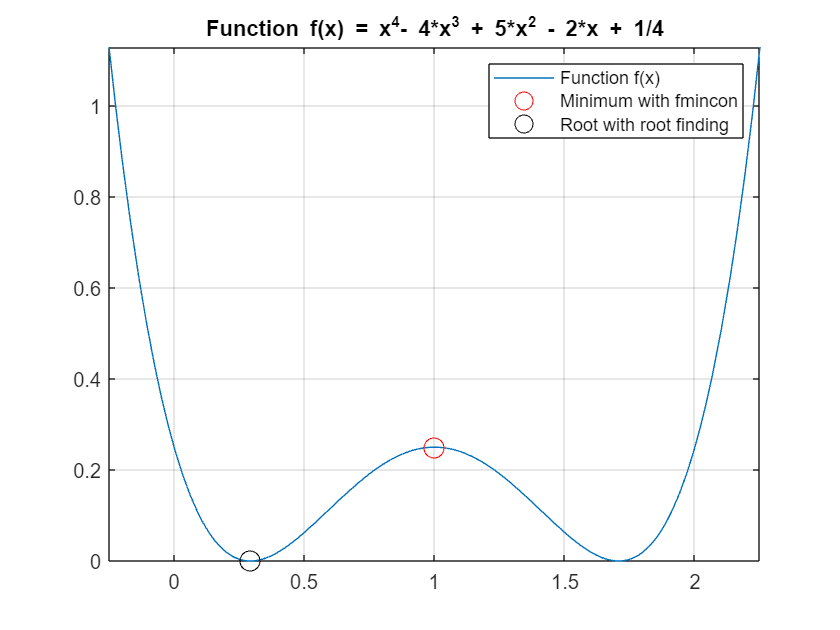

grid on
hold on
plot(root1, f(root1), 'ro', 'MarkerSize', 10); 
hold on
plot(root2, f(root2), 'ko', 'MarkerSize', 10);
title("Function f(x) = x^4- 4*x^3 + 5*x^2 - 2*x + 1/4");
legend('Function f(x)', 'Minimum with fmincon', 'Root with root finding');
hold off

**Second Function**

%% Function and initial value
f2 =  @(x)x^4 - 4*x^3 + 5*x^2 - 2*x;
x0 = 0.7;
%% Roots find with fmincon function and root finding
root1 = fmincon(f2,x0)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


root1 = 0.2929

root2 = root_finding(x0,f2,method)

root2 = 0.9995


%% Plot 
t = [-0.25 2.25];
clear fplot
fplot(f2,t);

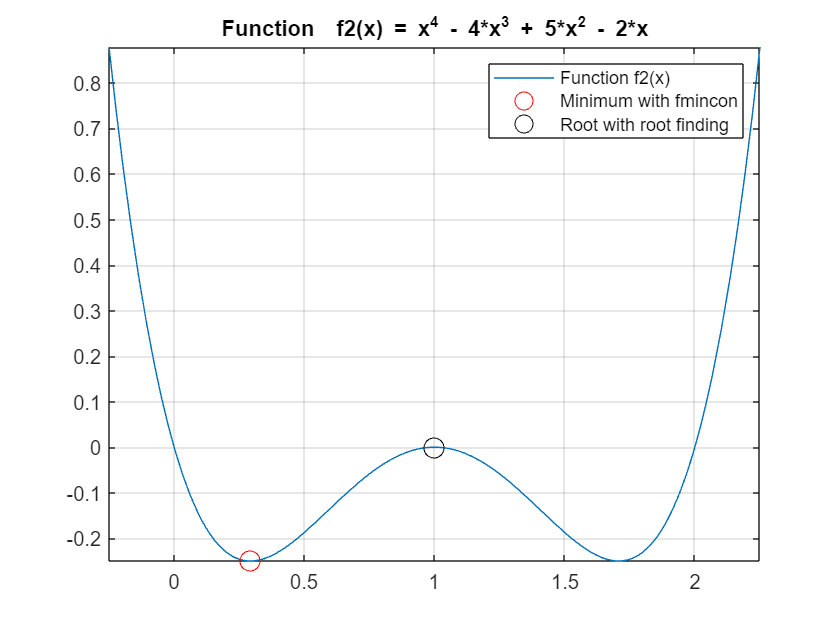

grid on
hold on
plot(root1, f2(root1), 'ro', 'MarkerSize', 10); 
hold on
plot(root2, f2(root2), 'ko', 'MarkerSize', 10);
title("Function  f2(x) = x^4 - 4*x^3 + 5*x^2 - 2*x");
legend('Function f2(x)', 'Minimum with fmincon', 'Root with root finding');
hold off